# Computer Assignment #6

## Ali Hamzehpour 810100129

### Part 1

In this part we want to calculate the speed and the distance of a vehicle by sending the signal and analysing the reflected signal we receive.

### 1-1

    First we plot the signal that we're sending. The signal is a cosine function as below:

#### 
$$x\left(t\right)=\cos \left(2\pi f_c t\right)$$


we assume that $f_c =5\mathrm{Hz}$ and sampling rate($\left.f_s \right)$ is 100Hz and we plot this function from $t_{\mathrm{start}} =0$ to $t_{\mathrm{end}} =1$

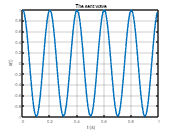

t_start = 0;
t_end = 1;
fc = 5;
fs = 100;

t = t_start: 1/fs: t_end-1/fs;
x_sent = cos(2 * pi * fc * t);

figure;
plot(t, x_sent, 'LineWidth', 2);
title("The sent wave")
ylabel("x(t)")
xlabel("t (s)")
grid on

### 1-2

    Now we plot the reflected signal that we receive from the vehicle. Because of the Doppler Efftect the frequency of the reflected signal will be different and also we will have a delay:

#### 
$$x\left(t\right)=\alpha \;\cos \left(2\pi \left(f_c +f_d \right)\left(t-t_d \right)\right)$$


Here $f_d$ is the frequency change caused by doppler effect. $t_d$ is the delay time. $\alpha$ is simply a coeeficient that show how the signal weakens.

the speed and distance of the vechile can be calculated by these equations:

#### 
$$f_d =\beta V$$


#### 
$$t_d =\frac{2}{c}R$$


where $c\;$is the speed of light and $\beta$ is a coeffiecient.

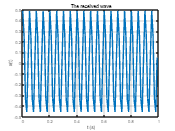

R = 250 * 1000;
v = 180 / 3.6;
beta = 0.3;
alpha = 0.5;

fd = beta * v;
C = 3e8;
P = 2 / C;

td =  P * R;

x_received = alpha * cos(2 * pi * (fd + fc)*(t - td));

figure;
plot(t, x_received, 'LineWidth', 2);
title("The received wave")
ylabel("x(t)")
xlabel("t (s)")
grid on

#### 1-3

    In this section we want to derive $t_d$ and $f_d$ from the received signal. we can rewrite the received signal like this:

#### 
$$y\left(t\right)=\alpha \;\cos \left(2\pi \left(f_c +f_d \right)\left(t-t_d \right)\right)$$


#### 
$$y\left(t\right)=\alpha \;\cos \left(2\pi \left(f_c +f_d \right)t-2\pi \left(f_c +f_d \right)t_d \right)$$


#### 
$$y\left(t\right)=\alpha \;\cos \left(2\pi f_{\mathrm{new}} t+\phi_{\mathrm{new}} \right)$$


so we can derive $f_{\mathrm{new}}$ and $\phi_{\mathrm{new}}$ from the fourier transform of the signal and then we can calculate $f_d$ and $t_d$ then we can calculate $V$ and $R$.

We write a function called *find_fd_td *which uses the fourier transform of the signal to derive those wanted values. $f_{\mathrm{new}}$ is where the abs of the fourier transform is maxiumum and $\phi_{\mathrm{new}}$ is the phase of the fourier transform in that maximum point.

function [fd, td] = find_fd_td(x_received, fs, fc)
    fourier = fftshift(fft(x_received));
    [~, mx_fourier] = max(abs(fourier));
    fd = abs(mx_fourier - floor(fs / 2) - 1) - fc; 

    phase = angle(fourier);
    td = phase(mx_fourier) / (2 * pi * (fd + fc));
end

    We also write a function called *find_v_R *which calculates distance and speed using $t_d$ and $f_d$

function [fd, td] = find_fd_td(x_received, fs, fc)
    fourier = fftshift(fft(x_received));
    [~, mx_fourier] = max(abs(fourier));
    fd = abs(mx_fourier - floor(fs / 2) - 1) - fc; 

    phase = angle(fourier);
    td = phase(mx_fourier) / (2 * pi * (fd + fc));
end

Finally we can test this functions with the received signal:

[fd_derived, td_derived] = find_fd_td(x_received, fs, fc);

[v_derived, R_derived] = find_v_R(fd_derived, td_derived, beta);

fprintf("v derived: %f(km/h) R derived: %f(km)\n ", v_derived * 3.6, R_derived / 1000);

v derived: 180.000000(km/h) R derived: 250.000000(km)
 

Which as you can see is exactly accurate.

#### 1-4

    In this section we add noise to the signal to see how our estimation works when the signal has noise:

noise = randn(1, length(x_received));
stds = 0 : 0.02 : 2;
error_v = zeros(1, length(stds));
error_R = zeros(1, length(stds));
best_std_R = 0;
best_std_v = 0;
error_threshold = 0.1;


for i = 1 : length(stds)
    std = stds(i);
    x_received = alpha * cos(2 * pi * (fd + fc)*(t - td)) + std * noise;
    [fd_derived, td_derived] = find_fd_td(x_received, fs, fc);
    [v_derived, R_derived] = find_v_R(fd_derived, td_derived, beta);
    if (abs(v_derived - v) < error_threshold * v)
        best_std_v = std;
    end
    if (abs(R_derived - R) < error_threshold * R)
        best_std_R = std;
    end
    error_v(i) = abs(v_derived - v) * 3.6;
    error_R(i) = abs(R_derived - R) / 1000;
end

mean_error_v = sum(error_v) / length(stds);
mean_error_R = sum(error_R) / length(stds);
fprintf("mean error v: %f(km/h) mean error R: %f(km)\n ", mean_error_v, mean_error_R);

mean error v: 67.009901(km/h) mean error R: 2323.035385(km)
 

fprintf("best std v: %f best std R: %f\n ", best_std_v, best_std_R);

best std v: 1.060000 best std R: 0.280000
 

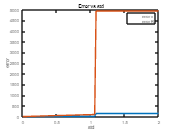

figure;
plot(stds, error_v, 'LineWidth', 2);
hold on
plot(stds, error_R, 'LineWidth', 2);
title("Error vs std")
ylabel("error")
xlabel("std")
legend("error v", "error R")

As you can see in the outputs, distance has more error that speed. The reason is because distance is calculated using phase of the fourier and speed is calculated using the frequency of the fourier transform. Noise has more effect on the phase and maximum frequency doesn't change that much when we have noise.

We assume that when our error is less than 10% of the accurate value, the estimation is ok. With this assumption, the distance reaches a wrong estimation with a lower std and speed needs a higher std.

#### 1-5

    In this section, we have two vehicles so the received signal is the sum of two cosine functions with these data:

#### 
$$\begin{array}{l}
R_1 =250\left(\mathrm{km}\right),V_1 =180\left(\frac{\mathrm{km}}{h}\right),\alpha_1 =0\ldotp 5\\
R_2 =200\left(\mathrm{km}\right),V_2 =216\left(\frac{\mathrm{km}}{h}\right),\alpha_1 =0\ldotp 6
\end{array}$$


First we plot this signal:

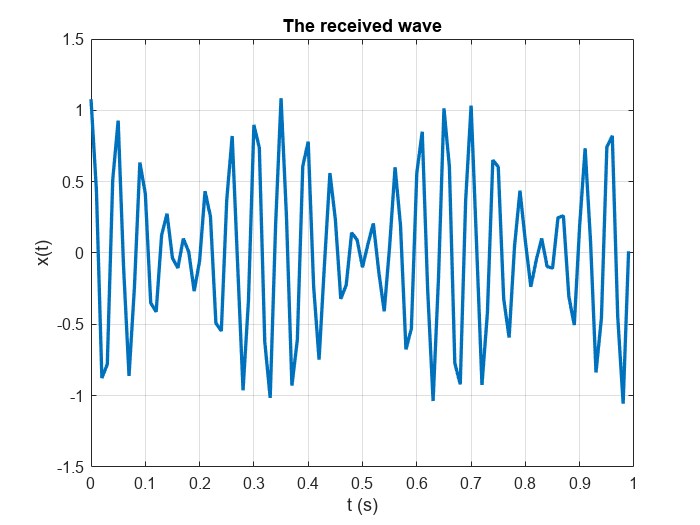

t_start = 0;
t_end = 1;
fc = 5;
fs = 100;
C = 3e8;
P = 2 / C;
beta = 0.3;


t = t_start: 1/fs: t_end-1/fs;

alpha1 = 0.5;
R1 = 250 * 1000;
v1 = 180 / 3.6;
fd1 = beta * v1;
td1 =  P * R1;

x_received1 = alpha1 * cos(2 * pi * (fd1 + fc)*(t - td1));

R2 = 200 * 1000;
v2 = 216 / 3.6;
alpha2 = 0.6;
fd2 = beta * v2;
td2 = P * R2;

x_received2 = alpha2 * cos(2 * pi * (fd2 + fc)*(t - td2));

x_received_tot = x_received1 + x_received2;

figure;
plot(t, x_received_tot, 'LineWidth', 2);
title("The received wave")
ylabel("x(t)")
xlabel("t (s)")
grid on

#### 1-6

    In order to derive the speed and distance of each vehicle, We calculate the fourier transform of the signal and Because it's the mixture of two cosine functions, It will have 4 peaks(2 peaks for each) and then we derive the frequency and phase of these cosine functions from the points that we have a peak.

We write a function called *find_fds_tds *that derive fd and tds of each cosine function like we explained and then we write a function called *find_vs_Rs *that calculates the speed and distance of each vechile using their frequencty and delay.

function [fds, tds] = find_fds_tds(x_received, fc, fs)
    fourier = fftshift(fft(x_received));
    [pks, locs] = findpeaks(abs(fourier));
    [pks, idx] = sort(pks, 'descend');
    locs = locs(idx);
    fds = zeros(1, 2);
    tds = zeros(1, 2);
    phase = angle(fourier);
    for i = 1:2
        fds(i) = abs(locs(2*i) - fs/2 - 1) - fc;
        tds(i) = abs(phase(locs(2*i))) / (2 * pi * (fds(i) + fc));
    end
end


function [vs, Rs] = find_vs_Rs(fds, tds, beta)
    C = 3e8;
    P = 2 / C;
    vs = zeros(1, 2);
    Rs = zeros(1, 2);
    for i = 1:2
        vs(i) = fds(i) / beta;
        Rs(i) = tds(i) / P;
    end
end

Now we can use these functions on the received signal:

[fds, tds] = find_fds_tds(x_received_tot, fc, fs);
[vs, Rs] = find_vs_Rs(fds, tds, beta);

fprintf("R(1) = %f(km), v(1) = %f(km/h)\n", Rs(1) / 1000, vs(1) * 3.6);

R(1) = 200.000000(km), v(1) = 216.000000(km/h)


fprintf("R(2) = %f(km), v(2) = %f(km/h)\n", Rs(2) / 1000, vs(2) * 3.6);

R(2) = 250.000000(km), v(2) = 180.000000(km/h)


As you can see the estimations are exactly accurate.

#### 1-7

***What happens if ***$V_1 =V_2$ ***but ***$R_1 \not= R_2$***? Can we still derive Vs and Rs? What is the minimum difference between ***$V_1$ ***and ***$V_2$ ***so we can be able to derive Vs and Rs?***

    No Because when Vs are equal, frequencies are also equal so we can't distinguish the frequenices using fourier transform. In order to be able to distinguish each frequncy, The difference between frequencies should be at least $\frac{f_s }{N}$ which is the resolution and is equal to $\frac{1}{T}$ so the minimum difference between Vs should be $\frac{1}{T\ldotp \beta }$

#### 1-8

***What if the distances are equal but the speeds are not?***

    Because in this situation the frequencies are not equal, we can distinguish each frequncy from each other so we can calculate the speeds and also we can calculate the distance using the phase of the maximum point.

#### 1-9

***What should we do when we don't know the number of vehicles?***

    We can still use a fourier transform and find the frequency of each function with each peak of the function.(if we have n cosine functions, we'll have 2*n peaks.) (If the speeds have enough differences between each other, we can distinguish each frequency using fourier transform.)

#### Part 2

#### 2-1

    First we define the mapset that maps each note name to a frequency then we generate the note sound of each note of the given music then we play the music.

We have a function called *generate_note_sound *that gets the note_name and map_set and also the timings and generate the array that contains the note sound of the given note.

We also have a function called *generate_music *which gets a an array of notes and use *generate_note_sound *to make the whole music.

function music = generate_music(notes, music_data, fs, tau)
    music_notes = cell(1, length(music_data));
    times = zeros(1, length(music_data));
    for i = 1:length(music_data)
        music_notes{i} = music_data{i}{1};
        times(i) = music_data{i}{2};
    end

    music = zeros(1, (sum(times) + length(times) * tau) * fs);

    for i = 1:length(music_notes)
        t_start = sum(times(1:i-1)) + (i-1) * tau;
        t_end = t_start + times(i);
        music(round(t_start * fs) + 1 : round(t_end * fs)) = generate_note_sound(music_notes(i), notes, fs, t_start, t_end);
    end
end

function x = generate_note_sound(note_name, notes, fs, t_start, t_end)
    note_index = find(strcmp(notes(1, :), note_name));
    f = notes{2, note_index};
    t = t_start : 1/fs : t_end - 1/fs;
    x = sin(2 * pi * f * t);
end

note_names = {'c', 'c#', 'd', 'd#', 'e', 'f', 'f#', 'g', 'g#', 'a', 'a#', 'b'};
frequencies = [523.25, 554.37, 587.33, 622.25, 659.25, 698.46, 739.99, 783.99, 830.61, 880.00, 932.33, 987.77];

notes = cell(2, length(note_names));

for i = 1:length(note_names)
    notes{1, i} = note_names{i};
    notes{2, i} = frequencies(i);
end

fs = 8000;
T = 0.5;
tau = 0.025;

music_data = {{'d', T/2}, {'d', T/2}, {'g', T}, {'f#', T}, {'d', T},...
        {'d', T/2}, {'e', T/2}, {'e', T/2}, {'d', T/2}, {'f#', T/2}, {'d', T/2}, {'e', T/2}, {'d', T/2}, {'e', T/2}, {'f#', T/2}, {'e', T/2},...
        {'d', T}, {'e', T}, {'f#', T}, {'e', T}, ...
        {'d', T/2}, {'e', T/2}, {'e', T/2}, {'d', T/2}, {'f#', T/2}, {'d', T/2}, {'e', T},...
        {'d', T}, {'e', T/2}, {'d', T/2}, {'f#', T}, {'e', T}, ...
        {'d', T}, {'e', T/2}, {'d', T/2}, {'f#', T}, {'e', T}, ...
        {'d', T/2}, {'d', T/2}, {'e', T}, {'f#', T/2}, {'e', T/2}, {'f#', T}, ...
        {'f#', T/2}, {'e', T/2}, {'f#', T}, {'f#', T}, {'d', T}
};


music = generate_music(notes, music_data, fs, tau);
audiowrite("music_2_1.wav", music, fs);

#### 2-2

    In this section, I used the first notes of the famous song "twinkle twinkle little star" to generate a new music.

my_music_data = {
    {'c', T/2}, {'c', T/2}, {'g', T/2}, {'g', T/2}, ...
    {'a', T/2}, {'a', T/2}, {'g', T},...
    {'f', T/2}, {'f', T/2}, {'e', T/2}, {'e', T/2}, ...
    {'d', T/2}, {'d', T/2}, {'c', T}, ...
}

music = generate_music(notes, my_music_data, fs, tau);
audiowrite("music_2_2.wav", music, fs);

#### 2-3

    In this section we have to derive the notes from a music file. First we split the segments using the silent time between each note and then we use fourier transform to find the dominant frequency in each note's sound and then we can derive the note name.

We define these functions to segmentize the music and then find each segment's notes:

function segments =  find_segments(music, fs, tau)
    zero_segment = zeros(1, round(tau * fs));
    current_note = [];
    segments = cell(1, 0);

    for i = 1 : length(zero_segment) : length(music) - length(zero_segment)
        segment = music(i : i + length(zero_segment) - 1);
        if sum(segment) == 0 
            if length(current_note) > 0
                segments{end + 1} = current_note;
                current_note = [];
            end
            continue;
        end
        current_note = [current_note, segment];
    end

    segments{end + 1} = current_note;

end

function x = find_segment_note(segment, notes, fs)
    fourier = fftshift(fft(segment));
    [~, mx_fourier] = max(abs(fourier));
    frequency = abs(mx_fourier * fs/(length(segment)) - floor(fs / 2) - 1);
    note_index = find_closest_frequency(notes, frequency);
    note_name = notes{1, note_index};
    fprintf("Note: %s time: T/%d\n", note_name, fs / (length(segment) * 2));
end

function note_index = find_closest_frequency(notes, frequency)
    note_index = 1;
    min_diff = abs(notes{2, 1} - frequency);
    for i = 2:length(notes)
        diff = abs(notes{2, i} - frequency);
        if diff < min_diff
            min_diff = diff;
            note_index = i;
        end
    end
end

Then we test it with the music file that we made:

[music, fs] = audioread("music_2_2.wav");
music = music';

segments = find_segments(music, fs, tau);

for i = 1 : length(segments)
    segment = segments{i};
    find_segment_note(segment, notes, fs);
end

Note: c time: T/2
Note: c time: T/2
Note: g time: T/2
Note: g time: T/2
Note: a time: T/2
Note: a time: T/2
Note: g time: T/1
Note: f time: T/2
Note: f time: T/2
Note: e time: T/2
Note: e time: T/2
Note: d time: T/2
Note: d time: T/2
Note: c time: T/1
